%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% System:
%   x' = -x + x^3
%   y' = -2y
%
% Goals:
%   - phase portrait (vector field + nullclines + trajectories)
%   - equilibria and local linearization (Jacobian, eigenvalues)
%
% Notes:
%   - System is separable: x and y evolve independently.
%   - Equilibria occur where x' = 0 and y' = 0.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;

%% Parameters and vector field
f = @(t,z) [ -z(1) + z(1)^3 ;  -2*z(2) ];   % z = [x;y]

%% Equilibria and local linearization
% Solve x' = -x + x^3 = x(x^2-1)=0 -> x* = -1,0,1
% Solve y' = -2y =0 -> y* = 0
eq = [ -1 0;  0 0;  1 0 ];   % rows are equilibria (x*,y*)

% Jacobian J = [df1/dx  df1/dy; df2/dx df2/dy]
% Here df1/dx = -1 + 3x^2, df1/dy=0; df2/dx=0, df2/dy=-2
J = @(x,y) [ -1 + 3*x^2, 0; 0, -2 ];

fprintf('Equilibria and eigenvalues:\n');

Equilibria and eigenvalues:


for i = 1:size(eq,1)
    x = eq(i,1); y = eq(i,2);
    A = J(x,y);
    lam = eig(A);
    fprintf('  (x*,y*) = (%.1f, %.1f): eigenvalues = (%.3f, %.3f)\n', x,y, lam(1), lam(2));
end

  (x*,y*) = (-1.0, 0.0): eigenvalues = (-2.000, 2.000)
  (x*,y*) = (0.0, 0.0): eigenvalues = (-2.000, -1.000)
  (x*,y*) = (1.0, 0.0): eigenvalues = (-2.000, 2.000)


fprintf('Interpretation:\n');

Interpretation:


fprintf('  (0,0) has eigenvalues (-1,-2): stable node.\n');

  (0,0) has eigenvalues (-1,-2): stable node.


fprintf('  (±1,0) have eigenvalues (2,-2): saddles.\n\n');

  (±1,0) have eigenvalues (2,-2): saddles.




%% Phase portrait settings
xlimv = [-1.6 1.6];
ylimv = [-1.2 1.2];

% Grid for vector field
nx = 25; ny = 25;
[xg,yg] = meshgrid(linspace(xlimv(1),xlimv(2),nx), linspace(ylimv(1),ylimv(2),ny));
ug = -xg + xg.^3;
vg = -2*yg;

figure('Color','w','Name','Example 1: Phase portrait');
hold on; box on;

% Vector field
quiver(xg,yg,ug,vg, 'AutoScale','on');
xlabel('x'); ylabel('y');
title('x''=-x+x^3,  y''=-2y  (vector field, nullclines, trajectories)');

% Nullclines:
% x-nullcline: x' = 0 -> x= -1, 0, 1 (vertical lines)
% y-nullcline: y' = 0 -> y=0 (horizontal line)
xline(-1,'k--','LineWidth',1.2); xline(0,'k--','LineWidth',1.2); xline(1,'k--','LineWidth',1.2);
yline(0,'k--','LineWidth',1.2);

% Mark equilibria
plot(eq(:,1), eq(:,2), 'ro', 'MarkerFaceColor','r', 'MarkerSize',6);

% Trajectories from multiple initial conditions
tspan = [0 5];
ICs = [ -1.01  1;
        -0.95  1;
        -0.65  1;
        -0.35  1;
        -0.05  1;
        -0.95  0;
         0.2  0.8;
         0.4  0.8;
         0.6  0.8;
         0.8  0.8;
         1.05  0.8;
        -1.05 -0.8;
        -0.95 -0.8;
         0.4 -0.6];

for k = 1:size(ICs,1)
    z0 = ICs(k,:)';
    [t,z] = ode45(f,tspan,z0);
    plot(z(:,1),z(:,2),'LineWidth',1.8);
end

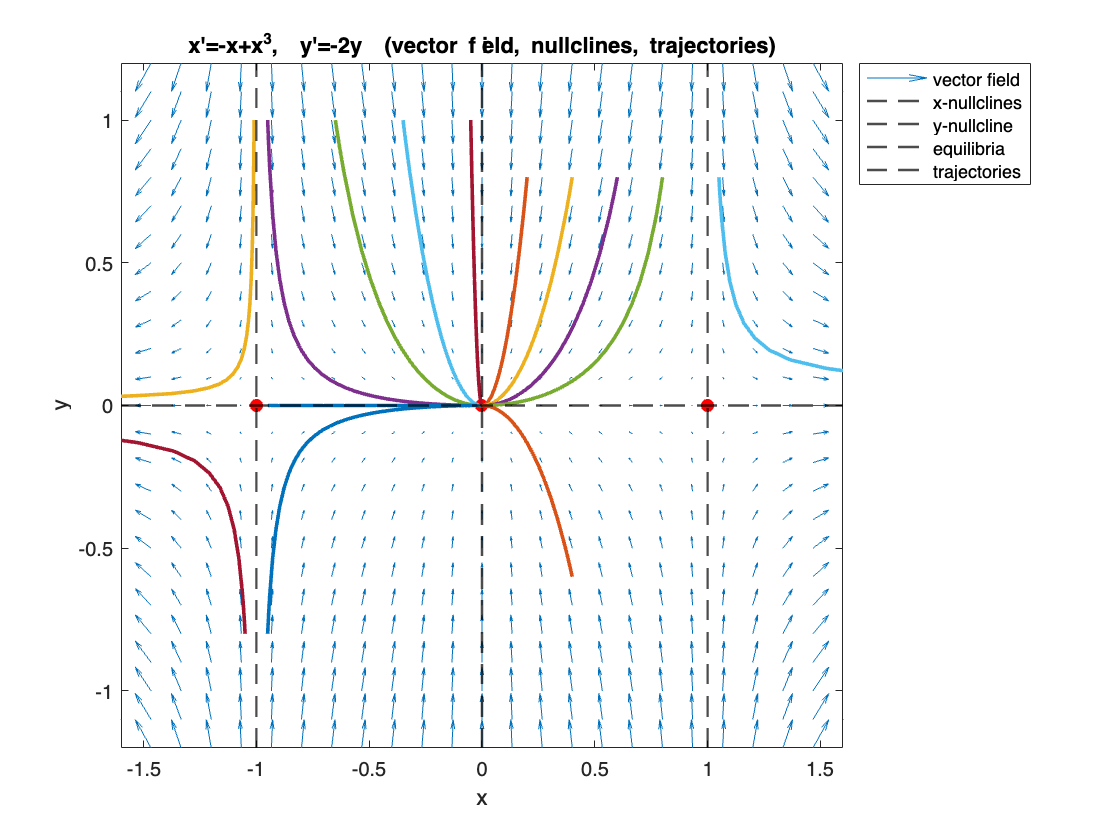


xlim(xlimv); ylim(ylimv);
legend({'vector field','x-nullclines','y-nullcline','equilibria','trajectories'}, ...
    'Location','bestoutside');